clear all
%f=figure(1);
R=[1.3107 0.7863 0.5044 0.4405 0.3903 0.3826];
%R1=[0 0 0 0 0 0 0 0]
D=[0.06 0.075 0.09000 0.120000 0.180000 0.24000]

D =     0.0600    0.0750    0.0900    0.1200    0.1800    0.2400


%D=linspace(10000,50000,5);
Biomass_CarryingCap=1e-7*[6.56 6.29 6.1 5.788 5.615 5.51 1.0];
x=D;
x1=D(1:3);
x2=D(4:6);
%.*Biomass_CarryingCap;
%x=D;
%x0=[0.005 0.005 0.02 0.02]
%y0=[0 4 4 0]
%c=[1 1 2 2]
%R(end) = NaN;
%x(7) = 0.02;
c=R;
c1=R(1:3);
c2=R(4:6);
f=figure();
%f=figure('Units','inches','Position',[0 0 3.25 3.0])
%colormap jet;
%patch(x,R,c,'EdgeColor','interp','Marker','o','MarkerFaceColor','flat')
%patch(x,R,c)
%colorbar;
plot(x,R,'k-','LineWidth',1)
hold on
scatter(x1,c1,[80 80 80 ],[0.5 0 0; 0.5 0 0; 0.5 0 0;])
scatter(x2,c2,[80 80 80 ],[0 0 0.5; 0 0 0.5; 0 0 0.5],'filled')
%clf
%set(gca,'colororder',[0.5 0 0; 0.5 0 0; 0.5 0 0; 0 0.5 0.5; 0 0 0.5; 0 0 0.5])
%hold on 
%plot(0.2:0.4:3.0,R1,'s-')
xlim([0.05 0.25000])
ylim([0 2.0])
xlabel('Biomass Diffusivity [cm^2/g sec]')
ylabel('Propagating interface roughness')
%x=[0.005 0.005 0.02 0.02]
%y=[0 4 4 0]
%c=[1 1 2 2]
%patch(x,y,c)
%legend('k=1','k=0')
%xBox = [0, 2.6, 2.6, 0]
%yBox = [0, 0, 12, 12]
%patch(xBox, yBox, 'black', 'FaceColor', [66, 129, 164]/255, 'FaceAlpha', 0.7);
%xBox = [2.6, 4.0, 4.0, 2.6]
%yBox = [0, 0, 12, 12]
%patch(xBox, yBox, 'black', 'FaceColor', [0.6350 0.0780 0.0840], 'FaceAlpha', 0.7);
text(0.060000,1.8,'furcated','FontSize',16, "Color",[0.5    0.0    0.0]);
text(0.150000,1.8, 'smooth','FontSize',16, "Color", [0.0    0.0    0.5] );
%set(gca,'FontSize',12)
ax=gca;
ax.FontSize=15

ax =   Axes with properties:

             XLim: [0.0500 0.2500]
             YLim: [0 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1614 0.7750 0.7636]
            Units: 'normalized'

  Show all properties


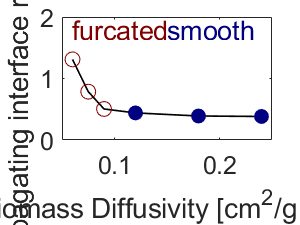

%hold off;
box on

exportgraphics(f,'RvsDNoise0.png')